# Multi-Point Constraint for beams (2D)

clear; close all; clc

*Class path:* `"../src/misc/MultiPointConstraint.m"`

In this demo, we model a resonator by means of a set of von Kàrman beam elements rigidely connected to lumped masses. This connection is performed with a master-slave node approach. In particular, we can write the following *linearized* relation to impose a rigid link between the master and the slave beam node DOFs:

${\left\lbrack \begin{array}{c}
u\\
v\\
\theta \;
\end{array}\right\rbrack }_{\textrm{slave}} =\left\lbrack \begin{array}{ccc}
1 & 0 & -\Delta y\\
0 & 1 & +\Delta x\\
0 & 0 & 1
\end{array}\right\rbrack {\left\lbrack \begin{array}{c}
u\\
v\\
\theta \;
\end{array}\right\rbrack }_{\textrm{master}}$ (1)

with $\Delta x=x_{\textrm{slave}} -x_{\textrm{master}}$ (same for $\Delta y$). In short, we can rewrite the above as $u_s =R\;u_m$.

#### Convention

In the present framework, multiple disconnected beam structures are defined using a single assembly. As a consequence, considering for instance the stiffness matrix, we will have a *single matrix* $K_b$ pertaining to a vector $u_b$ which contains the DOFs of *all beams*. We call $K_{b,c}$ and $u_{b,c}$ their constrained counterparts, respectively. Notice that $u_{b,c}$ still contains the slave DOFs.

For each j-th master node, we define a lumped mass (stiffness) matrix $K_{m,j}$. These are then collected in a block diagonal matrix $K_M =\textrm{blkdiag}\left(K_{m,1} ,\ldotp \ldotp \ldotp ,K_{m,M} \right)$. This matrix pertains to a vector $u_M$, which contains all master node DOFs. Its contrained counterpart is $u_{M,c}$.

The stiffness matrix pertaining to all DOFs (master, slaves, free and constrained) then writes:

$K_{\textrm{full}} =\left\lbrack \begin{array}{cc}
K_b  & \\
 & K_M 
\end{array}\right\rbrack \longleftrightarrow \left\lbrack \begin{array}{c}
u_b \\
u_M 
\end{array}\right\rbrack =u_{\textrm{full}}$    (2)

The transformation matrix $T_{\textrm{mpc}}$ we construct is such that:

${\bar{K} }_{\textrm{mpc}} =T_{\textrm{mpc}}^T \left\lbrack \begin{array}{cc}
K_{b,c}  & \\
 & K_M 
\end{array}\right\rbrack T_{\textrm{mpc}} \;\;\longleftrightarrow \;\;\left\lbrack \begin{array}{c}
u_{b,c}^r \\
u_M 
\end{array}\right\rbrack ={\bar{u} }_{\textrm{mpc}}$    (3)

where $u_{b,c}^r$ is the vector of structural (beam) DOFs, constrained and slave ones removed (using Eq.(1)). 

After this, the rows/columns related to the fixed master DOFs are removed:

$K_{\textrm{mpc}} \longleftrightarrow \;u_{\textrm{mpc}} =\left\lbrack \begin{array}{c}
u_{b,c}^r \\
u_{M,c} 
\end{array}\right\rbrack$    (4)

The equations of motion finally write:

$M_{\textrm{mpc}} \;{\ddot{u} }_{\textrm{mpc}} +K_{\textrm{mpc}} u_{\textrm{mpc}} +K_{2,\textrm{mpc}} :\left(u_{\textrm{mpc}} \otimes u_{\textrm{mpc}} \right)+K_{3,\textrm{mpc}} \vdots \left(u_{\textrm{mpc}} \otimes u_{\textrm{mpc}} \otimes u_{\textrm{mpc}} \right)=F_{\textrm{mpc}} \left(t\right)$   (5)

where we also included the nonlinear quadratic and cubic stiffness terms of the elastic restoring force.

Note: all matrices and tensors returned by the `MultiPointConstraint` object are provided in the form above. To go back to $u_{\textrm{full}}$, the `unconstrain_mpc_vector` method is provided.

## Model definition

% geometry
len = 1;        	% length
width = 1e-2;    	% width in the bending direction
thickness = 1e-2;	% thickness in the third dimension

% mesh settings
nElements = 10;
dx = len / nElements;

% material properties
E       = 210e9;    % Young's modulus
rho     = 7800;     % density
nu      = 0.3;      % nu

myMaterial  = KirchoffMaterial();
set(myMaterial,'YOUNGS_MODULUS',E,'DENSITY',rho,'POISSONS_RATIO',nu);

% Element (same element all across the domain)
myElementConstructor = @()BeamElement(thickness, width, myBeamMaterial);

element_constructor{1} = @()BeamElement(thickness, width,     myMaterial);
element_constructor{2} = @()BeamElement(thickness, width * 2, myMaterial);


We define the mesh as the union of 2 different set of elements, each representing a separate structure. The connection between the 2 will be later performed through the MPC.

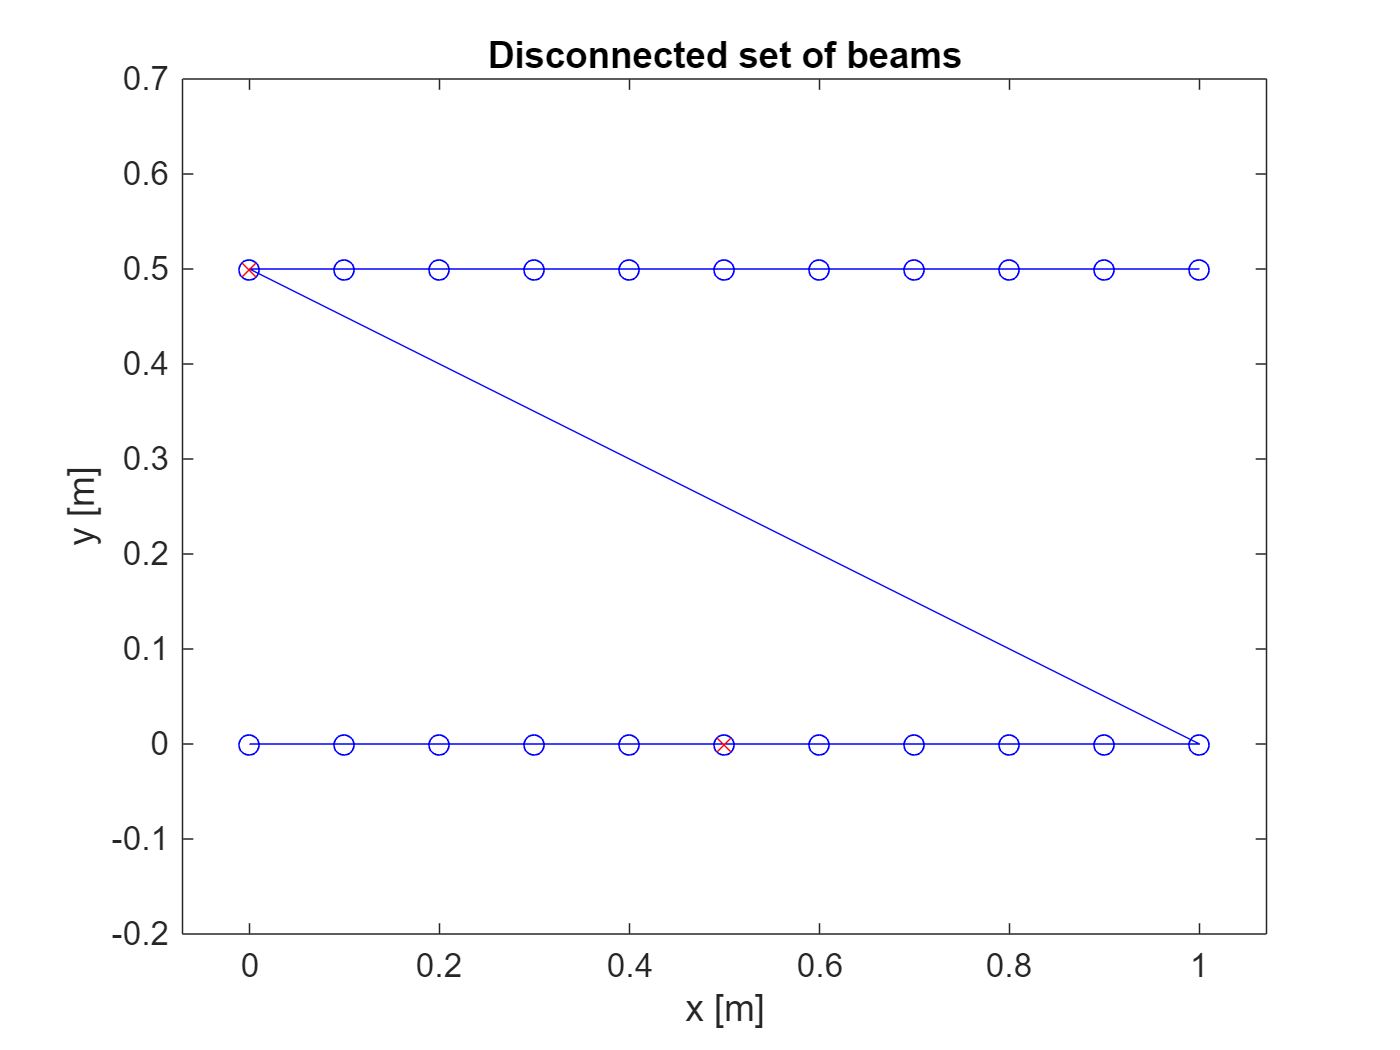

% Mesh
x1 = (0:dx:len).';      % 1st beam x-coordinates
x2 = x1;                % add a 2nd beam, parallel to the 1st one
x = [x1; x2];
nn = size(x,1);         % number of nodes
Dy = 0.5;               % y-offset
y1 = zeros(nn/2,1);     % 1st beam y-coordinates
y2 = Dy*ones(nn/2,1);   % 2nd beam y-coordinates
y = [y1; y2];
Nodes = [x, y]; % add a 2nd beam with a Dy offset

Elements{1} = [1:nn/2-1;2:nn/2].';  % 1st beam elements
Elements{2} = Elements{1}+nn/2;     % add 2nd beam elements
myMesh = Mesh(Nodes);
myMesh.create_elements_table(Elements, element_constructor);

% Boundary conditions
% fix vertical displacement and rotation of the first node of the top beam
fixed_nodes(1) = nn/2+1;
myMesh.set_essential_boundary_condition(fixed_nodes(1),2:3,0);
% fix the vertical displacement of the midspan node of the bottom beam. Get
% the node ID using node location coordinates:
fixed_nodes(2) = myMesh.get_nodeIDs_from_location([len/2, 0]);
myMesh.set_essential_boundary_condition(fixed_nodes(2),2,0);

% note: don't fix slave nodes! constrain master nodes instead.

figure
plot(x, y, 'b-o')
hold on; plot(Nodes(fixed_nodes,1), Nodes(fixed_nodes,2),'rx')
axis equal; ylim([-0.2 0.7]); title('Disconnected set of beams')
xlabel('x [m]'); ylabel('y [m]')

Notice that the way the `Elements` matrix has been defined, the two structures are effectively disconnected (the line connecting the last node of the bottom beam and the first node of the top beam is just a plot issue).

## Master and Slave nodes

We define 2 master nodes with lumped masses, defined as homogeneus rectangles of sides a and b:

a = 0.5;
b = 0.55;

% master node coordinates
xG1 = len+a/2;
yG1 = Dy/2;
xG2 = -a/2;
yG2 = 0;


Let us define a matrix with master coordinates and information about which dofs are constrained (0=free, 1=constrained). In this example, the rotation of the first mass is fixed:

master_nodes = [xG1, yG1, 1, 0, 1
                xG2, yG2, 0, 0, 0];

% lumped masses profiles (for plot)
mass_xy{1} = [xG1+[-a a a -a]'/2, yG1+[-b -b b b]'/2];  % a rectangular rigid mass
mass_xy{2} = [xG2+[-a a a -a]'/2, yG2+[-b -b b b]'/2];


Finally, let us define the `mpc` matrix which relates masters and slaves, lumped mass/stiffness matrices and the `MultiPointConstraint` object.

% mpc: the 1st column contains the slave node IDs, while the 2nd one
% contains the respective master node IDs (ordered as defined in
% master_nodes)
mpc = [nn/2, 1;
       nn,   1;
       1,    2];

% Lumped mass and stiffness matrices
m = a*b*thickness*rho;
J = 1/12*a*b*(a^2 + b^2)*thickness*rho;
Mm{1} = diag([m,m,J]);
Mm{2} = diag([m,m,J]);
Km{1} = zeros(3);
Km{2} = zeros(3);
% note: the master node coincides with the baricenter, and the moment of
% inertia J should be defined accordingly. Springs are attached to the
% respective master nodes.

% MPC: a subclass of Assembly (inherits all properties and methods)
obj = MultiPointConstraint(myMesh, mpc, master_nodes, Mm, Km);
obj.nDOFs

ans = struct with fields:
            all_structural: 66
                all_slaves: 9
               all_masters: 6
    constrained_structural: 3
       constrained_masters: 2
           free_structural: 63
              free_masters: 4
                       mpc: 58


% (optional) to use the "mpc_plot" method, add the following information to the object:
obj.PLOT.mass_xy = mass_xy;
obj.PLOT.elem = Elements;

Plot of the model built so far. Master nodes are plotted in red, slaves in yellow, master-slave virtual connections are represented by dashed red lines, while blue circles around a master nodes indicate the number of fixed DOFs.

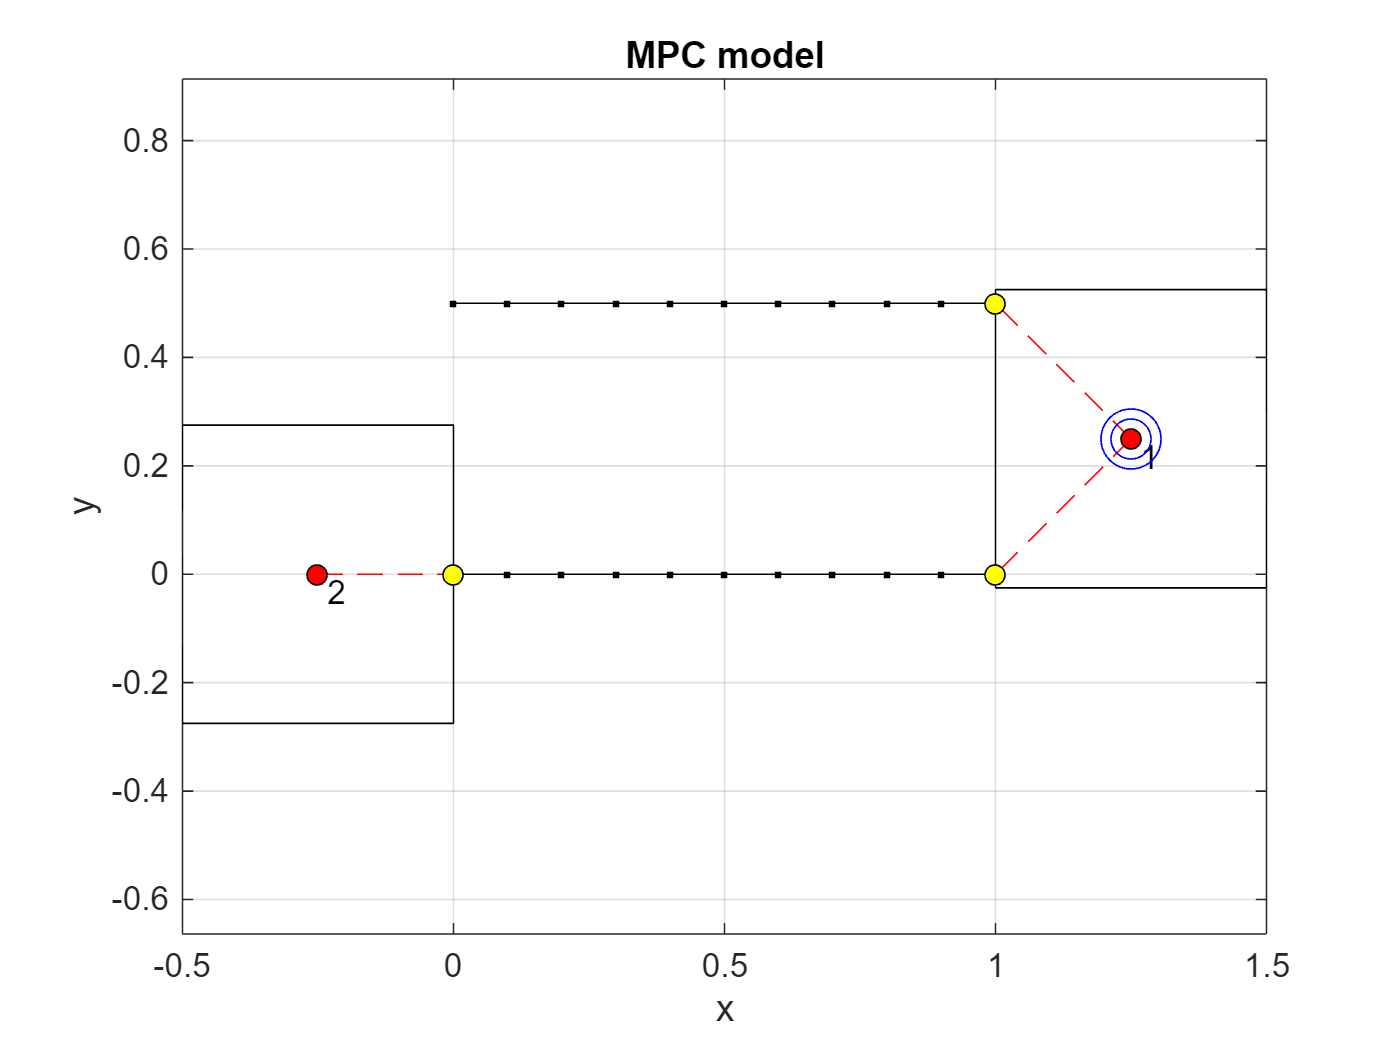

figure
obj.mpc_plot
title('MPC model')

## Eigenvalues and Eigenvectors

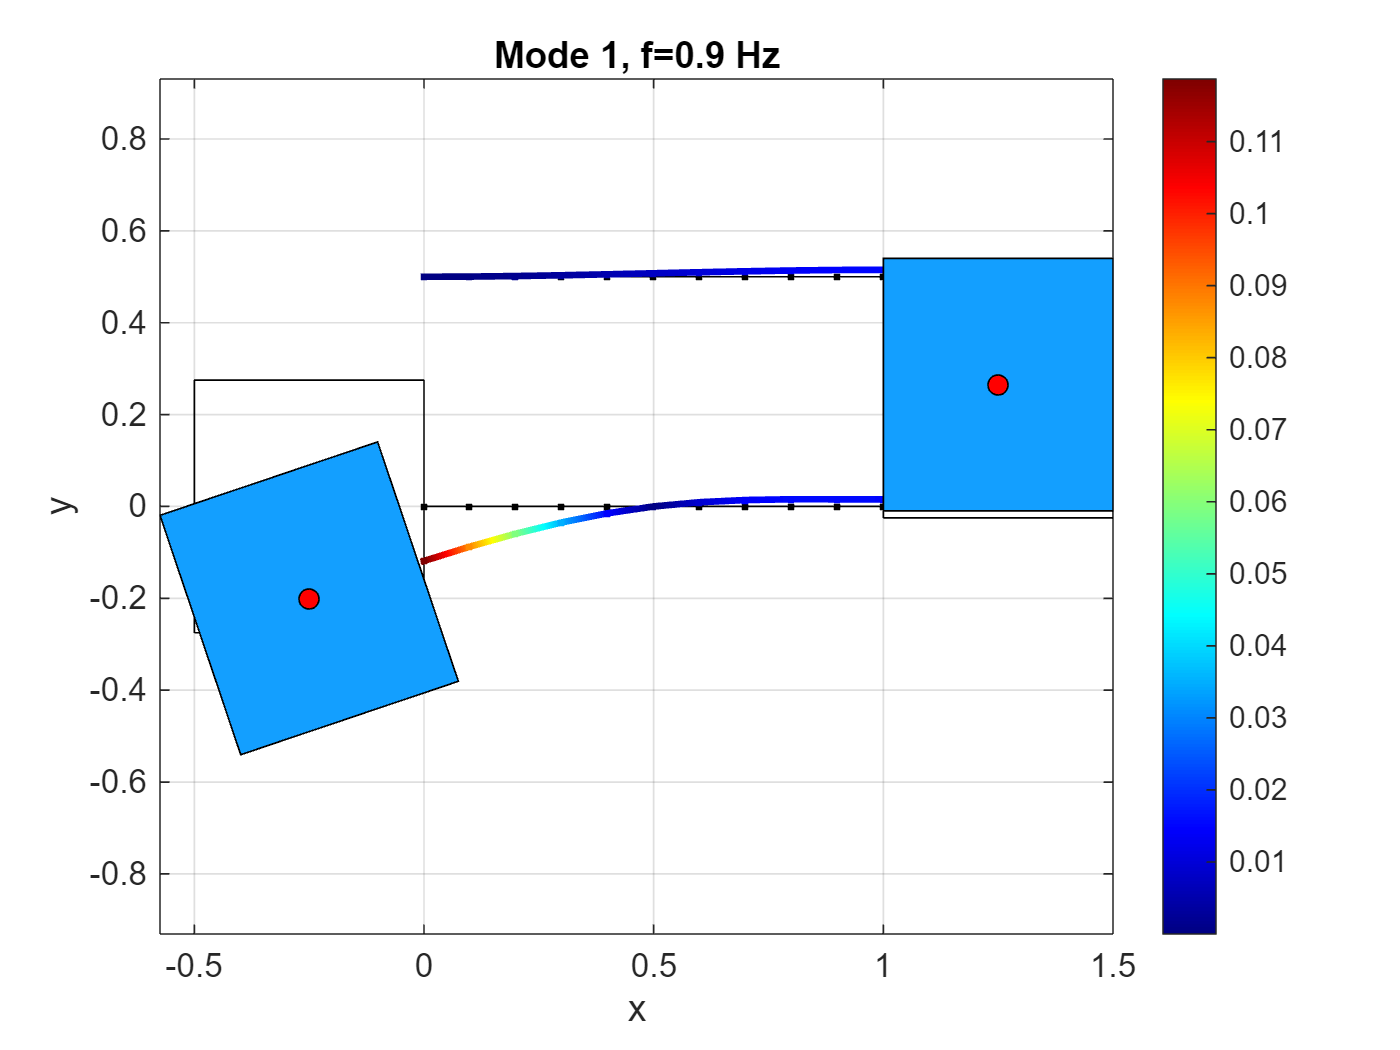

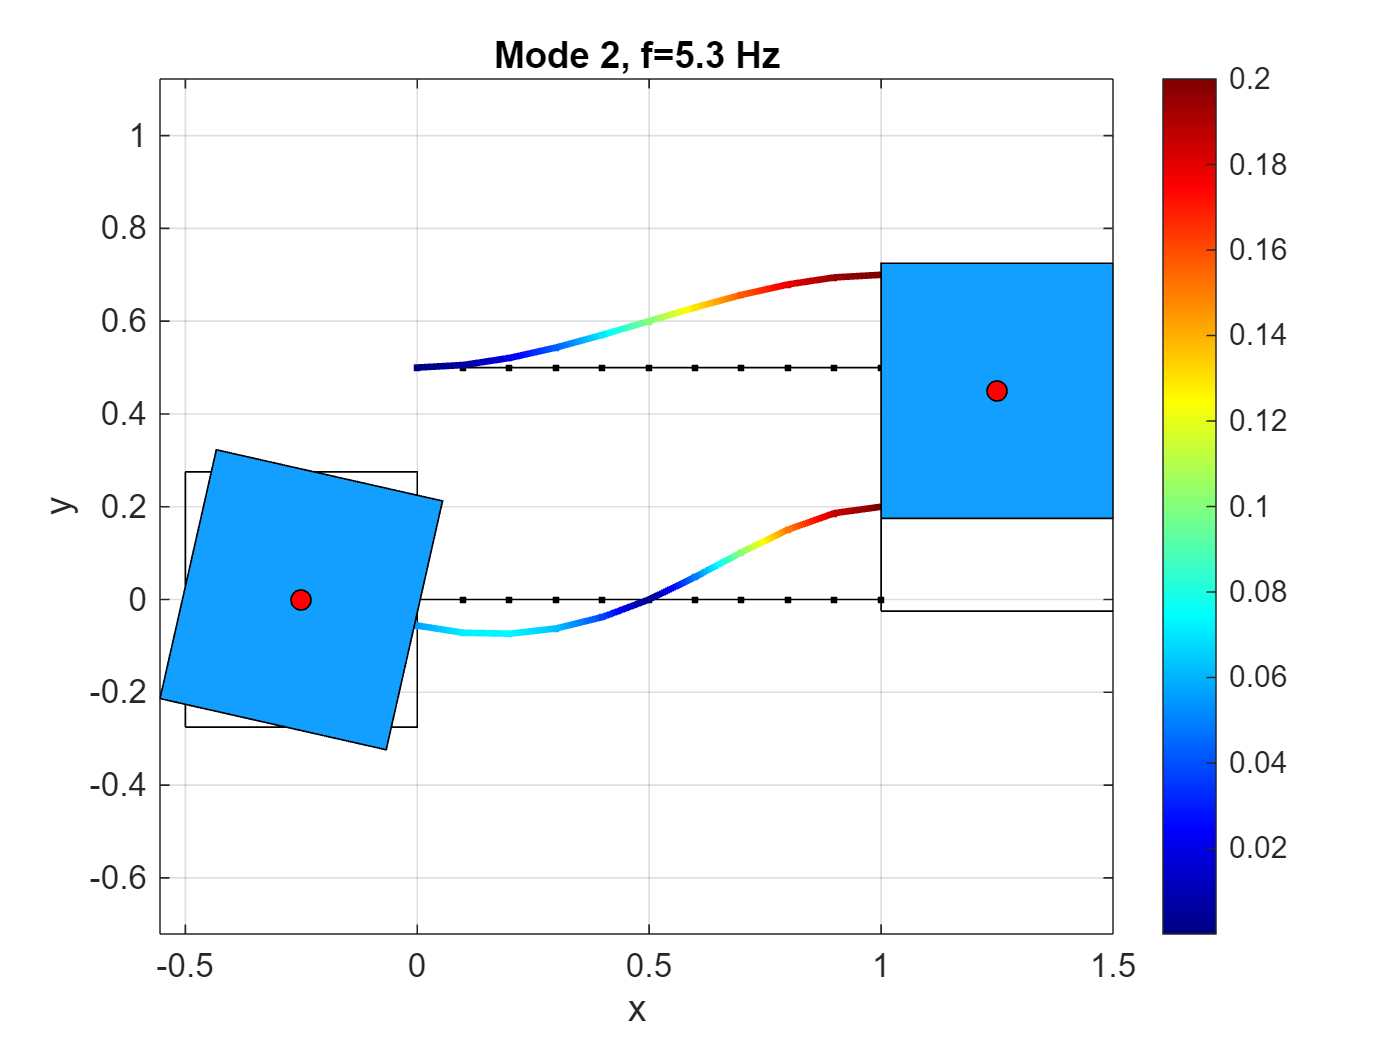

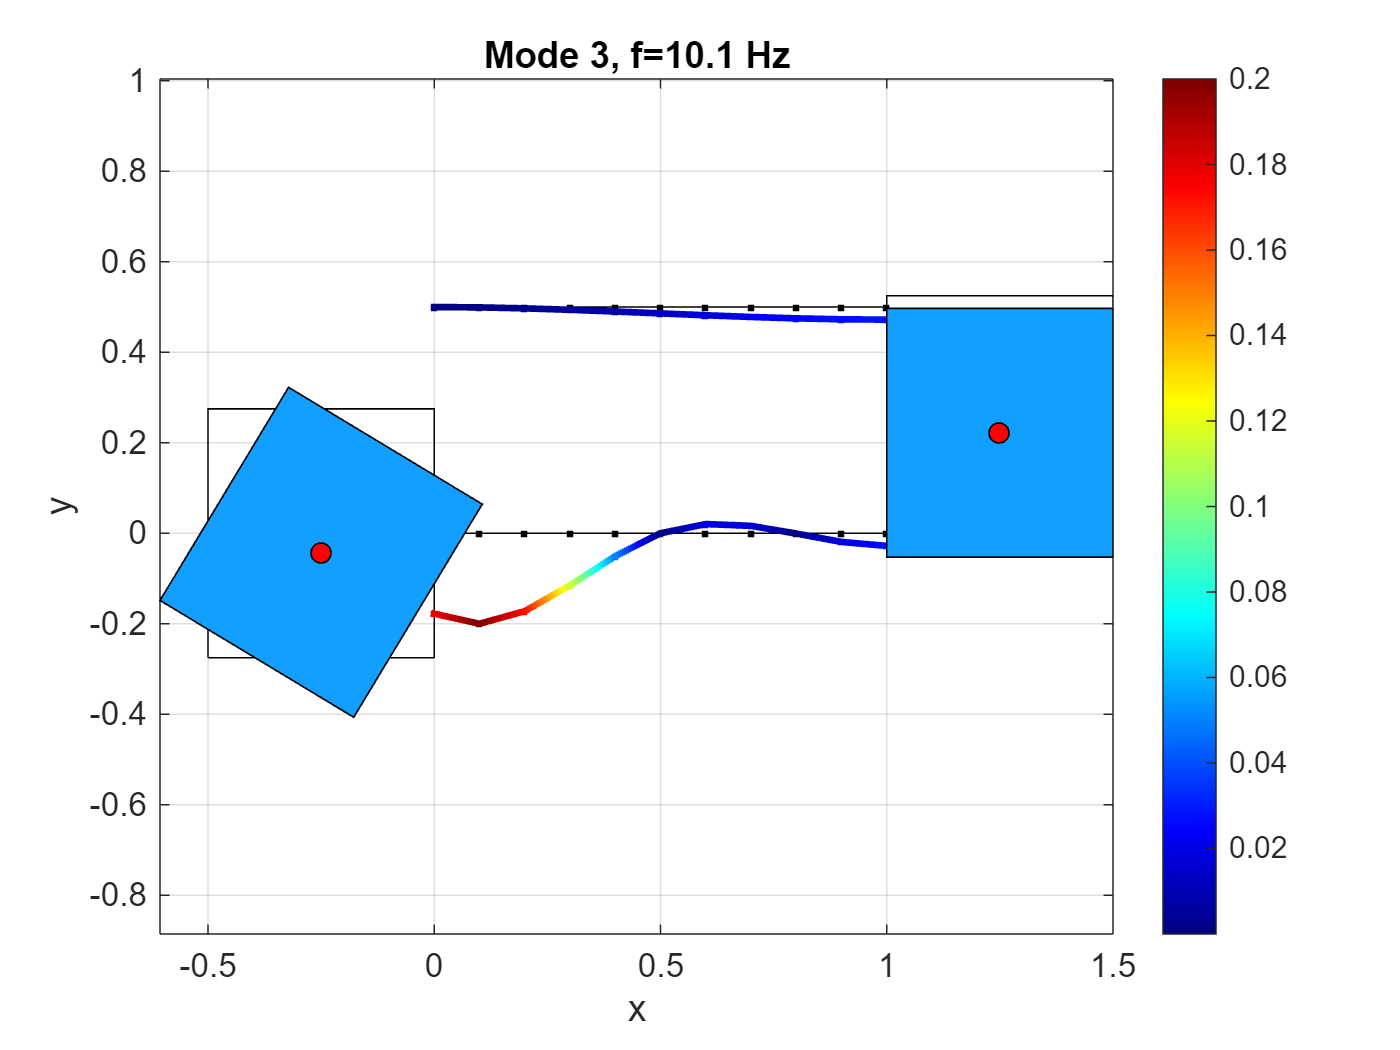

u0   = zeros( myMesh.nDOFs, 1);
Kmpc = obj.tangent_stiffness_and_force(u0,{zeros(3), zeros(3)});
Mmpc = obj.mass_matrix;

% Eigenvalue problem                                               
n_VMs = 7; % first n_VMs modes with lowest frequency calculated 
[Phi1,om2] = eigs(Kmpc, Mmpc, n_VMs, 'SM');
[om, ind] = sort(sqrt(diag(om2)));
f0 = om/2/pi;

for imod = 1 : 3
    figure
    scale = .2;
    obj.mpc_plot(Phi1(:,imod),scale)
    title(sprintf('Mode %d, f=%.1f Hz',imod,f0(imod)))
end

Note: Eq. (1) is linearized, so for large rotations we expect the model to fail in accurately describe the motion of the system (this is also appearent in the last plot, for the rotation of the left mass).

## Tensor construction

% quadratic and cubic stiffness tensors
[K2_mpc, K3_mpc] = obj.mpc_tensors;
fprintf('non-zero elements in K2: %d / %d \n', nnz(K2_mpc), prod(size(K2_mpc))) %#ok<PSIZE>

non-zero elements in K2: 711 / 195112 


fprintf('non-zero elements in K3: %d / %d \n', nnz(K3_mpc), prod(size(K3_mpc))) %#ok<PSIZE>

non-zero elements in K3: 1016 / 11316496 


## Static test

NL = 1; % toggle nonlinear analysis
Fext = zeros( obj.nDOFs.mpc , 1 );
Fext(end,1) = 1e3; % vertical force on the left mass
res = @(u) Kmpc*u + NL*double(ttv(K2_mpc,{u,u},[3 2]) + ...
    ttv(K3_mpc,{u,u,u},[4 3 2])) - Fext; % residual function to solve (using tensors)
u0 = Kmpc\Fext; % initial guess
options = optimoptions('fsolve','SpecifyObjectiveGradient',false,...
            'MaxIterations',10000,'Display','iter-detailed',MaxFunctionEvaluations=1e5);
ueq = fsolve(@(u) res(u), u0, options); % solve for equilibrium


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0         59         4.13369e+17                         4.5e+18              1
     1        118         7.32058e+16              1         9.14e+17              1
     2        177         7.96743e+13        1.51959         5.02e+16            2.5
     3        178         7.96743e+13        3.15675         5.02e+16            3.8
     4        237         3.55072e+13       0.789187         1.08e+16          0.789
     5        296         2.11417e+13       0.789187         5.08e+15          0.789
     6        297         2.11417e+13       0.789187         5.08e+15          0.789
     7        356         1.27527e+13       0.197297         5.33e+15          0.197
     8        415         9.25185e+12       0.197297         3.11e+15          0.197
     9        474         6.63262e+12       0.197297         2.3

rn = norm(res(ueq)); % residual norm
uu = obj.unconstrain_mpc_vector(ueq);
uu0 = obj.unconstrain_mpc_vector(u0);
fprintf('Residual norm: %g\nMax x-displacement: %g (lin: %g) \nMax y-displacement: %g (lin: %g)\n',...
    rn, max(abs(uu(1:3:end))), max(abs(uu0(1:3:end))), ...
    max(abs(uu(2:3:end))), max(abs(uu0(2:3:end))))

Residual norm: 4.0929e-08
Max x-displacement: 0.0306974 (lin: 0) 
Max y-displacement: 0.164321 (lin: 1.28571)


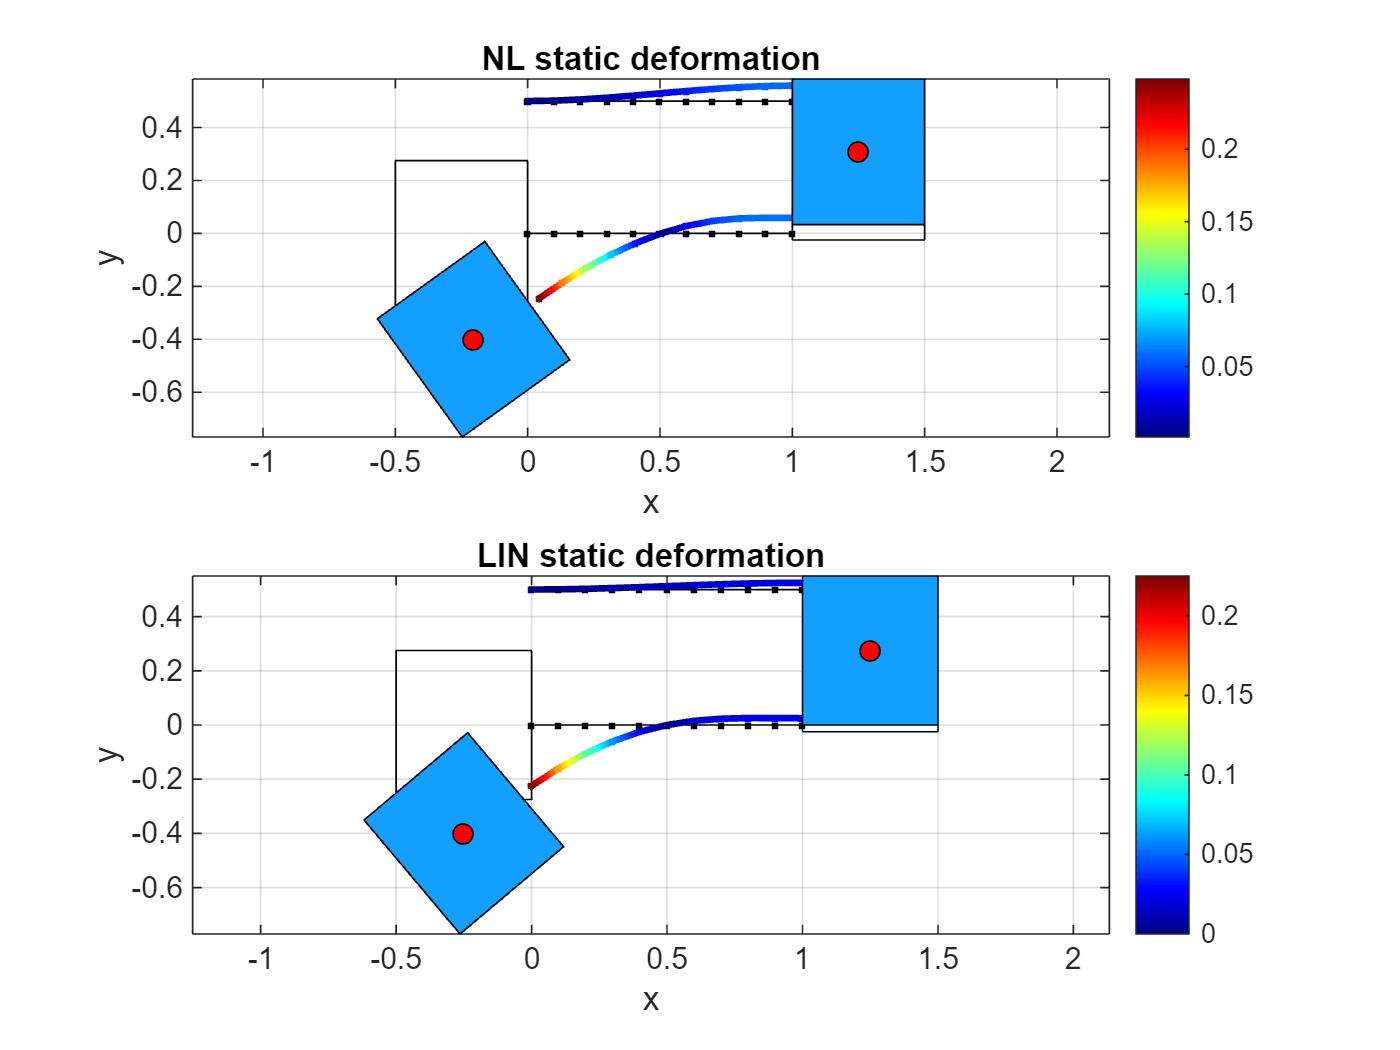

figure
subplot 211
obj.mpc_plot(ueq, 0.4)
title('NL static deformation')
subplot 212
obj.mpc_plot(u0, 0.4)
title('LIN static deformation')